**Problema 5**. Deduceti seria Taylor pentru ln(1 + x) si aproximati ln 2 folosind primii 8 termeni. Cati termeni sunt necesari pentru a obtine ln 2 cu 5 zecimale corecte? La fel pentru ln 1+x/1−x .

syms x f n
f=log(1+x);
assume(n>0);
n=8;
Tnf=taylor(f,x,0,'order',n)

$$Tnf = \frac{x^{7}}{7}-\frac{x^{6}}{6}+\frac{x^{5}}{5}-\frac{x^{4}}{4}+\frac{x^{3}}{3}-\frac{x^{2}}{2}+x$$

vrez1=vpa(subs(Tnf,x,1),10)

$$vrez1 = 0.7595238095$$

n=1;
fr=sym(1)/sym(100000);
while(abs(subs(Tnf,x,1))>fr)
    Tnf=taylor(f,x,0,'order',n);
    n=n+10000;
end
n-1

ans = 10000

syms x f n
assume(n>0);
f=log((1+x)/(1-x));
n=8;

Tnf=taylor(f,x,0,'order',n+1)

$$Tnf = \frac{2\,x^{7}}{7}+\frac{2\,x^{5}}{5}+\frac{2\,x^{3}}{3}+2\,x$$

vrez2=vpa(subs(Tnf,x,1),10)

$$vrez2 = 3.352380952$$

n=1;
fr=sym(1)/sym(100000);
while(abs(subs(Tnf,x,sym(1)/sym(3))-subs(f,x,sym(1)/sym(3)))>fr)
    Tnf=taylor(f,x,0,'order',n+1);
    n=n+1;
end
n

n = 10

**Problema 7 (Aproximare cu serii MacLaurin)**. O functia f ∈ C n[a, b] se poate aproxima, utilizand seria Maclaurin trunchiata, printr-un polinom de grad n f(x) ≈ Tn(x) = Xn i=0 cix i , unde ci = f (i) (0)/i!.

 (a)    Reprezentati grafic si comparati graficele lui f(x) = e x si ale polinoamelor (T2f) (x), (T3f) (x), (T4f)               (x), (T5f) (x). Aproximeaza multumitor polinoamele Tnf de grad mare functia e x pe un interval din ce in ce mai mare centrat ın jurul originii? 

(b)     Repetati pentru g(x) = ln(1 + x).

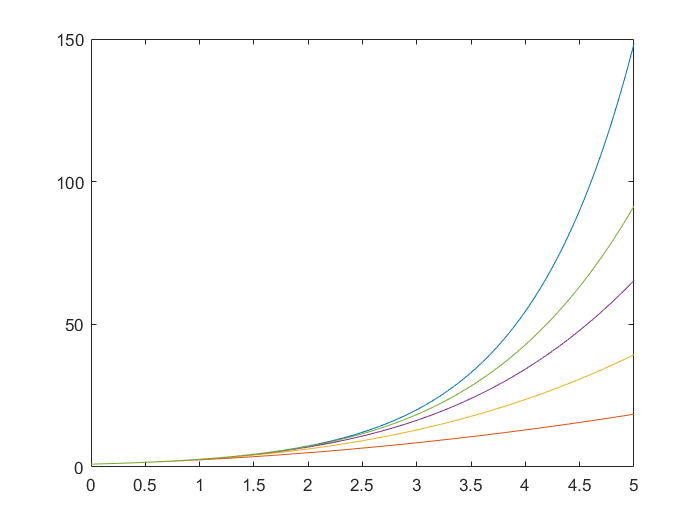

figure
f=exp(x);
p = linspace(0,5,100);
plot(p,exp(p))
n=2;
hold on 
while(n<6)
 y2 = taylor(f,x,0,'order',n+1);
 n=n+1;
 plot(p,subs(y2,x,p))   
end
%legend("e^x","T1")
hold off

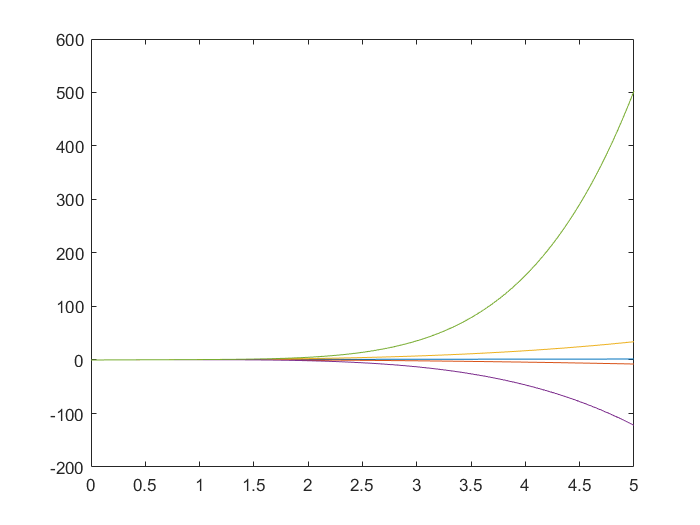

figure
syms x;
f=log(1+x);
p = linspace(0,5,100);
plot(p,log(1+p))
n=2;
hold on 
while(n<6)
 y2 = taylor(f,x,0,'order',n+1);
 n=n+1;
 plot(p,subs(y2,x,p))   
end
hold off

**Problema 8 (Aproximare Pad´e rat¸ional˘a)**. Aproximarea Pad´e rat¸ional˘a este cea mai bun˘a aproximare a unei funct¸ii printr-o funct¸ie rat¸ional˘a de ordin (m, k) dat. Se define¸ste ca fiind o aproximare rat¸ional˘a de grad (m, k) dat care repro�duce valorile funct¸iei si derivatelor ei pˆana la ordinul m + k. Ea d˘a adesea aproxim˘ari mai bune decˆat seriile Taylor trunchiate ¸si uneori lucreaz˘a chiar ¸si atunci cˆand seria Taylor nu converge! ˆIn loc s˘a utiliz˘am polinoame de grad mare, putem utiliza cˆaturi de polinoame de grad mic. Aceste aproxim˘ari se numesc aproxim˘ari rat¸ionale.

 Fie f(x) ≈ pm(x) qk(x) = Pm i=0 aix i Pk j=0 bjx j = Rm,k(x), unde b0 = 1. Aici am normalizat prin b0 6= 0 iar valorile lui m ¸si k se presupun a fi modeste. Alegem cei k coeficient¸i bj ¸si cei m + 1 coeficient¸i ai din Rm,k astfel ˆıncˆat Rm,k s˘a reproduc˘a valorile lui f ¸si ale unui num˘ar specificat de derivate ale ei ˆın punctul fixat x = 0. Construim ˆıntˆai seria Maclaurin trunchiat˘a Pn i=0 cix i , unde ci = f (i) (0)/i! ¸si ci = 0 pentru i < 0. Apoi, egal˘am primele m + k + 1 derivate ale lui Rm,k ˆın raport cu x ˆın x = 0 cu primii m + k + 1 coeficient¸i ci . 

a) Implementati aproximarea Pade pentru f, k, m date. 

b) Determinati functiile rationale R1,1(x) ¸si R2,2(x) pentru f(x) = e x . Reprezentati grafic si comparati graficele lui f(x) = e x , R1,1 ¸si R2,2. Sunt satisfacatoare aceste aproximatii rationale ale lui e x pe [−1, 1]? Cum se comporta com�parativ cu seriile Maclaurin trunchiate din problemele precedente? 

c) Repetati pentru aproxim˘arile R2,2(x) ¸si R3,1(x) ale functiei g(x) = ln(1 + x).

b)

syms f x
f = exp(x);
R11 = simplify(Problema8(f, 1, 1, x))

$$R11 = -\frac{x+2}{x-2}$$

R22 = simplify(Problema8(f, 2, 2, x))

$$R22 = \frac{x^{2}+6\,x+12}{x^{2}-6\,x+12}$$

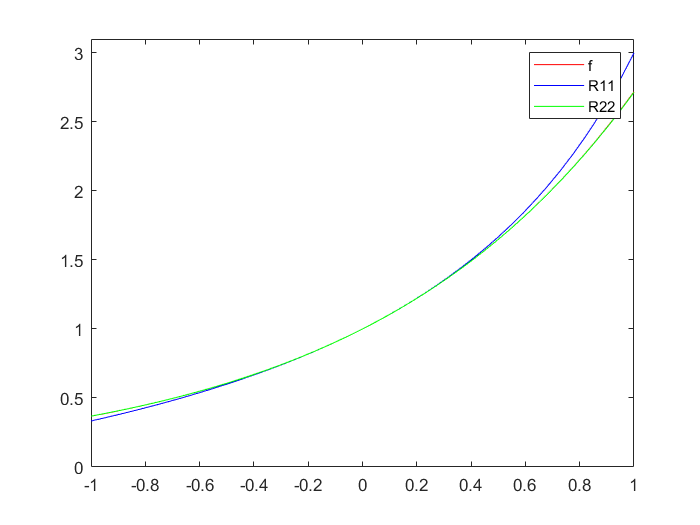


figure
fplot(f, [-1,1], 'red')
ylim([0, 3.1])
hold on
fplot(R11, [-1,1], 'blue')
fplot(R22, [-1,1], 'green')
hold off
legend("f","R11","R22")

c)

syms g x
g = log(1+x);
R31 = Problema8(g, 3, 1, x)

$$R31 = \frac{-\frac{x^{3}}{24}+\frac{x^{2}}{4}+x}{\frac{3\,x}{4}+1}$$

R22 = Problema8(g, 2, 2, x)

$$R22 = \frac{\frac{x^{2}}{2}+x}{\frac{x^{2}}{6}+x+1}$$

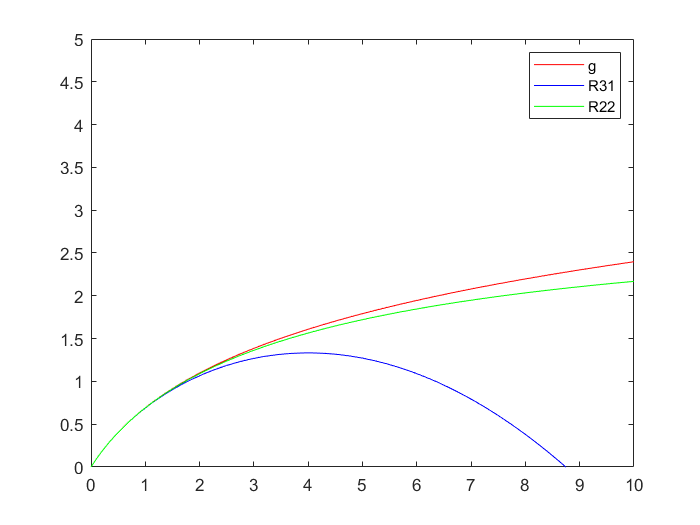


figure
fplot(g, [0,10], 'red')
ylim([0, 5])
hold on
fplot(R31, [0,10], 'blue')
fplot(R22, [0,10], 'green')
hold off
legend("g","R31","R22")

a)

function R = Problema8(f,m,k,x)
syms C a R bt vp
c=zeros(m+k+1,1,'sym');
if m>k
    b=zeros(m+1,1,'sym');
else
    b=zeros(k+1,1,'sym');
end
a=zeros(1,m+1,'sym');

for p=0:m+k
    c(p+1)=subs(diff(f,x,p),x,0)/factorial(p);
end

j=0:k-1;
C=toeplitz(c(m+j+1),c(m-j+1)); %C, c
bv=-c(m+(1:k)+1);
b(2:k+1)=C\bv;
b(1)=1;

syms j
for j=0:m
    a(j+1)=sym('0');
    for l=0:j
        a(j+1)=a(j+1)+c(j-l+1)*b(l+1); 
    end
end
vp=sum(a.*x.^(0:m));
vq=sum(b(1:k+1)'.*x.^(0:k));
R=vp/vq;
end